I = imread('..\datasets\segmentation-evaluation-database\1obj\100_0109\src_color\100_0109.png');

h = 0.6;

I = imresize(I, [50 NaN]);
[rows, cols, ~] = size(I);

X = image_transform(I);

hs = linspace(0.1, 1, 10);
Ks = zeros(length(hs), 1);
for i = 1:length(hs)
    [A, C, T] = mean_shift(X, 'gaussian', hs(i), 0.1);
    Ks(i) = max(A);
end

ans =    -1.7087   -1.7368   -1.7983   -1.8496   -1.8745   -1.8586   -1.8505   -1.7514   -1.7602   -1.8002   -1.7997   -1.7802   -1.7542   -1.7367   -1.9214   -1.9688   -1.9342   -1.8877   -1.8672   -1.8570   -1.8262   -1.4258   -1.4607   -1.7119   -1.1136    0.4442    0.9063    0.9027    0.4016   -0.7682    0.2036    0.7882    0.4112    0.2174    0.0528    0.0524    0.2534    0.4095   -0.8217   -0.7050    5.6689    2.8768    2.1001    2.2361    0.6426    0.3980   -0.1975    0.3202    0.9687    0.1933
   -2.6781   -2.5745   -2.4995   -2.4560   -2.4565   -2.4207   -2.4032   -2.3840   -2.3543   -2.2587   -2.2166   -2.1462   -2.1038   -2.0763   -1.9518   -1.8632   -1.8177   -1.8166   -1.7604   -1.6588   -1.5973   -1.3201   -1.2474   -1.3186   -0.9750   -0.2425   -0.1013   -0.1039   -0.2913   -0.6008   -0.2941   -0.1445   -0.2113   -0.2888   -0.3755   -0.3687   -0.3836   -0.2842    0.6751    0.9630    0.5709    1.4802    1.7490    1.7310    1.6826    1.3918    1.2669    1.5039    1.5404   

X =    -0.0226   -0.0230   -0.0238   -0.0245   -0.0248   -0.0246   -0.0245   -0.0232   -0.0233   -0.0238   -0.0238   -0.0236   -0.0232   -0.0230   -0.0254   -0.0261   -0.0256   -0.0250   -0.0247   -0.0246   -0.0242   -0.0189   -0.0193   -0.0227   -0.0147    0.0059    0.0120    0.0120    0.0053   -0.0102    0.0027    0.0104    0.0054    0.0029    0.0007    0.0007    0.0034    0.0054   -0.0109   -0.0093    0.0751    0.0381    0.0278    0.0296    0.0085    0.0053   -0.0026    0.0042    0.0128    0.0026
   -0.1177   -0.1131   -0.1098   -0.1079   -0.1079   -0.1063   -0.1056   -0.1047   -0.1034   -0.0992   -0.0974   -0.0943   -0.0924   -0.0912   -0.0857   -0.0819   -0.0799   -0.0798   -0.0773   -0.0729   -0.0702   -0.0580   -0.0548   -0.0579   -0.0428   -0.0107   -0.0045   -0.0046   -0.0128   -0.0264   -0.0129   -0.0063   -0.0093   -0.0127   -0.0165   -0.0162   -0.0169   -0.0125    0.0297    0.0423    0.0251    0.0650    0.0768    0.0760    0.0739    0.0611    0.0557    0.0661    0.0677    0

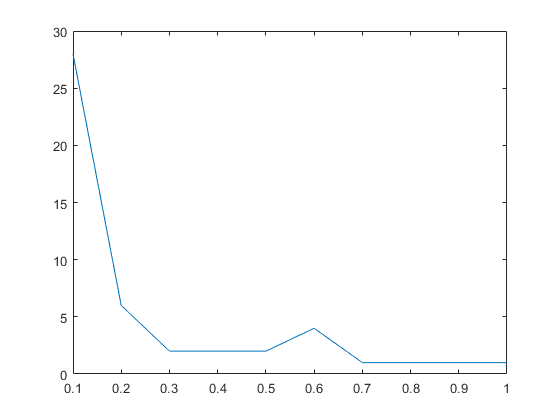

plot(hs, Ks);

[A, C, T] = mean_shift(X, 'gaussian', 0.25, 0.1);

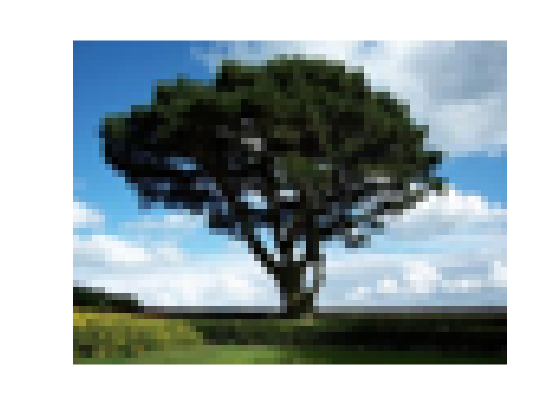

figure
imshow(I, 'InitialMagnification', 'fit');

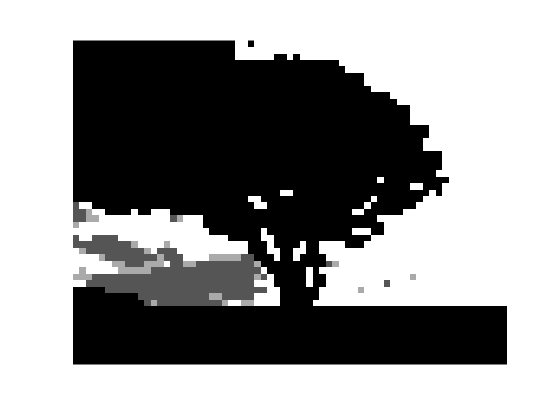

figure
imshow(reshape(A, rows, cols), [], 'InitialMagnification', 'fit');

std(X, 0, 2)

ans =     0.0448
    0.1486
    1.0000
    0.2946
    0.2931



I_out = rescale(reshape(A, [rows, cols]));
T_out = rescale(reshape(T, [rows, cols]));

[coeff, score] = pca(C');
C_ = (coeff * score');
[~, index] = sort(C_(1,:));
index(A)

ans =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1
